%calculating the mean first passage time analytically/numerically 
%to investigate effect of invader-substrate mismatch position on DNA/DNA
%toehold exchange kinetics including spontaneous incumbent dissociation

b = 20 %define branch migration domain length

b = 20

g = 6 %define invader toehold length

g = 6

g2 = 2 %define incumbent toehold length

g2 = 2


bg2 = b + g2 %define branch migration domain + incumbent toehold length 

bg2 = 22


R = 1.987/1000 % universal gas constant in kcal/K/mol 

R = 0.0020

temp = 298.15 %temperature in K

temp = 298.1500

%free energy parameter
dGassoc = 2.6*R*temp

dGassoc = 1.5403

dGbp = -2.52*R*temp

dGbp = -1.4929

dGp = 3.6*R*temp

dGp = 2.1327

dGmm = 9.5*R*temp

dGmm = 5.6280

dGbm = 7.4*R*temp 

dGbm = 4.3839

%absolute rate constant
k_bp = 5.4*10^7

k_bp = 54000000

k_eff = zeros(1,20)

k_eff =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = zeros(1, 20)

first_pass_time =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


prob_unbound = zeros(1, 20)

prob_unbound =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


k_eff_perf = zeros(1, 20)

k_eff_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time_perf = zeros(1, 20)

first_pass_time_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


prob_unbound_perf = zeros(1, 20)

prob_unbound_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



%loop through mismatch positions
for m = 1:20

    %define forward and reverse transition rates
    k_AA = 0;
    k_AB1 = k_bp * exp(-dGassoc/(R*temp)) * (5*10^-8)
    k_B1A = k_bp * exp(dGbp/(R*temp))
    k_BC1ij = k_bp;
    k_BC1ji = k_bp * exp(dGbp/(R*temp));
    k_C1f = k_bp * exp(-(dGbm + dGp)/(R*temp))
    k_Cf = k_bp * exp(-dGbm/(R*temp))
    k_Cr = k_bp * exp(-dGbm/(R*temp));
    k_Crm = k_bp * exp((dGmm - dGbm)/(R*temp))
    k_Crm_end = k_bp * exp((dGmm - dGbm - dGp)/(R*temp))
    k_DC = k_bp * exp(-(dGbm + dGp)/(R*temp))
    k_DEij = k_bp * exp(dGbp/(R*temp));
    k_DEji = k_bp;
    k_EF = k_bp * exp(dGbp/(R*temp));
    k_FE = 0
    k_FF = 1    
    
    %create arrays for forward and reverse transition rates for
    %mismatch-free system
    Kf_perf = [k_FF, k_EF, repmat(k_DEij, [1, g2-1]), repmat(k_Cf, [1, b-1]), k_C1f, repmat(k_BC1ij, [1, g-2]), k_BC1ij, k_AB1]
    Kb_perf = [k_FE, repmat(k_DEji, [1, g2-1]), k_DC, repmat(k_Cr, [1, b-1]), k_BC1ji, repmat(k_BC1ji, [1, g-2]), k_B1A, k_AA]
        
    %create arrays of forward and reverse transition rates for mismatch
    %system
    if m == b
        Kf = [k_FF, k_EF, repmat(k_DEij, [1, g2-1]), repmat(k_Cf, [1, b-1]), k_C1f, repmat(k_BC1ij, [1, g-2]), k_BC1ij, k_AB1]
        Kb = [k_FE, repmat(k_DEji, [1, g2-1]), k_DC, repmat(k_Cr, [1, b-1]), k_BC1ji, repmat(k_BC1ji, [1, g-2]), k_B1A, k_AA]
        Kb(b+g2-m+1) = k_Crm_end
        
        %define spontaneous incumbent dissociation rates
        Koff = [repmat(0, [1, g2+1])]; 
        for n = g2 + 1:bg2-1
            Koff = horzcat(Koff, [k_bp*exp(-(n*(-dGbp))/(R*temp))]);
        end
        Koff = horzcat(Koff, [repmat(0, [1, g+1])])
        
    else
        Kf = [k_FF, k_EF, repmat(k_DEij, [1, g2-1]), repmat(k_Cf, [1, b-1]), k_C1f, repmat(k_BC1ij, [1, g-2]), k_BC1ij, k_AB1]
        Kb = [k_FE, repmat(k_DEji, [1, g2-1]), k_DC, repmat(k_Cr, [1, b-1]), k_BC1ji, repmat(k_BC1ji, [1, g-2]), k_B1A, k_AA]
        Kb(b + g2 - m + 1) = k_Crm
        
        %define spontaneous incumbent dissociation rates
        Koff = [repmat(0, [1, g2+1])]; 
        for n = g2 + 1:bg2-1
            Koff = horzcat(Koff, [k_bp*exp(-(n*(-dGbp))/(R*temp))]);
        end
        Koff = horzcat(Koff, [repmat(0, [1, g+1])])
        
    end
    
    Pn_jN_1 = zeros(1,numel(Kf))
    jn_jN_1 = zeros(1,numel(Kf))
    Pn_jN_1 (1) = 0;
    jn_jN_1 (1) = 1;
    
    %calculate flux between each state for mismatch system
    for Pn = 2:numel(Kf)
        Pn_jN_1(Pn)  = 1/Kf(Pn) * jn_jN_1 (Pn-1) + (Kb(Pn-1)/Kf(Pn))*Pn_jN_1(Pn-1);
        jn_jN_1(Pn) = jn_jN_1(Pn-1) + Koff(Pn) * Pn_jN_1(Pn);
    end
    
    Pn_jN_1_perf = zeros(1,numel(Kf_perf))
    jn_jN_1_perf = zeros(1,numel(Kf_perf))
    Pn_jN_1_perf (1) = 0;
    jn_jN_1_perf (1) = 1;
        
    %calculate flux between each state for mismatch-free system
    for Pn = 2:numel(Kf_perf)
        Pn_jN_1_perf(Pn)  = 1/Kf_perf(Pn) * jn_jN_1_perf(Pn-1) + (Kb_perf(Pn-1)/Kf_perf(Pn))*Pn_jN_1_perf(Pn-1);
        jn_jN_1_perf(Pn) = jn_jN_1_perf(Pn-1) + Koff(Pn) * Pn_jN_1_perf(Pn);
    end
        
    first_pass_time (m) = (1/jn_jN_1(end-1))*sum(Pn_jN_1) %first passage time for mismatch system
    k_eff (m) = 1/(first_pass_time (m)*(5*10^-8)); %effective rate constant for mismatch system
    prob_unbound(m) = Pn_jN_1(end)/sum(Pn_jN_1) %prob of being in unbound state for mismatch system
    
    first_pass_time_perf (m) = (1/jn_jN_1_perf(end-1))*sum(Pn_jN_1_perf) %first passage time for mismatch-free system
    k_eff_perf(m) = 1/(first_pass_time_perf(m)*(5*10^-8)); %effective rate constant for mismatch-free system
    prob_unbound_perf(m) = Pn_jN_1_perf(end)/sum(Pn_jN_1_perf) %prob of being in unbound state for mismatch-free system
    
end

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 4.4097e+08

k_Crm_end = 1.2049e+07

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf_perf = 	1.0e+07 *

    0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf = 	1.0e+07 *

         0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kf = 	1.0e+07 *

    0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb = 	1.0e+07 *

         0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kb = 	1.0e+08 *

         0    0.5400    0.0000    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    4.4097    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434         0


Koff = 	1.0e+04 *

         0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+04 *

    2.0167         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9853         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     7.0196         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9959         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 4.4097e+08

k_Crm_end = 1.2049e+07

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf_perf = 	1.0e+07 *

    0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf = 	1.0e+07 *

         0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kf = 	1.0e+07 *

    0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb = 	1.0e+07 *

         0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kb = 	1.0e+08 *

         0    0.5400    0.0000    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    4.4097    0.0003    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434         0


Koff = 	1.0e+04 *

         0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+04 *

    2.0167    1.9075         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9853    0.9850         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     7.0196    7.0196         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9959    0.9959         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 4.4097e+08

k_Crm_end = 1.2049e+07

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf_perf = 	1.0e+07 *

    0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf = 	1.0e+07 *

         0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kf = 	1.0e+07 *

    0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb = 	1.0e+07 *

         0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kb = 	1.0e+08 *

         0    0.5400    0.0000    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    4.4097    0.0003    0.0003    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434         0


Koff = 	1.0e+04 *

         0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+04 *

    2.0167    1.9075    1.7983         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9853    0.9850    0.9846         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     7.0196    7.0196    7.0196         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9959    0.9959    0.9959         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 4.4097e+08

k_Crm_end = 1.2049e+07

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf_perf = 	1.0e+07 *

    0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf = 	1.0e+07 *

         0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kf = 	1.0e+07 *

    0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kb =          0    0.5400    0.0000    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    4.4097    0.0003    0.0003    0.0003    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     2.0167    1.9075    1.7983    1.6891         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9853    0.9850    0.9846    0.9842         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     7.0196    7.0196    7.0196    7.0196         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9959    0.9959    0.9959    0.9959         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 4.4097e+08

k_Crm_end = 1.2049e+07

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kb =          0    0.5400    0.0000    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    4.4097    0.0003    0.0003    0.0003    0.0003    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     2.0167    1.9075    1.7983    1.6891    1.5797         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9853    0.9850    0.9846    0.9842    0.9839         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     7.0196    7.0196    7.0196    7.0196    7.0196         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9959    0.9959    0.9959    0.9959    0.9959         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 4.4097e+08

k_Crm_end = 1.2049e+07

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kb =          0    0.5400    0.0000    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    4.4097    0.0003    0.0003    0.0003    0.0003    0.0003    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     2.0167    1.9075    1.7983    1.6891    1.5797    1.4703         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9853    0.9850    0.9846    0.9842    0.9839    0.9835         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     7.0196    7.0196    7.0196    7.0196    7.0196    7.0196         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9959    0.9959    0.9959    0.9959    0.9959    0.9959         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 4.4097e+08

k_Crm_end = 1.2049e+07

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kb =          0    0.5400    0.0000    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    4.4097    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     2.0167    1.9075    1.7983    1.6891    1.5797    1.4703    1.3607         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9853    0.9850    0.9846    0.9842    0.9839    0.9835    0.9832         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 4.4097e+08

k_Crm_end = 1.2049e+07

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kb =          0    0.5400    0.0000    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    4.4097    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     2.0167    1.9075    1.7983    1.6891    1.5797    1.4703    1.3607    1.2511         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9853    0.9850    0.9846    0.9842    0.9839    0.9835    0.9832    0.9828         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 4.4097e+08

k_Crm_end = 1.2049e+07

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kb =          0    0.5400    0.0000    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    4.4097    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     2.0167    1.9075    1.7983    1.6891    1.5797    1.4703    1.3607    1.2511    1.1414         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9853    0.9850    0.9846    0.9842    0.9839    0.9835    0.9832    0.9828    0.9824         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 4.4097e+08

k_Crm_end = 1.2049e+07

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kb =          0    0.5400    0.0000    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    4.4097    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     2.0167    1.9075    1.7983    1.6891    1.5797    1.4703    1.3607    1.2511    1.1414    1.0317         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9853    0.9850    0.9846    0.9842    0.9839    0.9835    0.9832    0.9828    0.9824    0.9821         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 4.4097e+08

k_Crm_end = 1.2049e+07

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kb =          0    0.5400    0.0000    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    4.4097    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     2.0167    1.9075    1.7983    1.6891    1.5797    1.4703    1.3607    1.2511    1.1414    1.0317    0.9218         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9853    0.9850    0.9846    0.9842    0.9839    0.9835    0.9832    0.9828    0.9824    0.9821    0.9817         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 4.4097e+08

k_Crm_end = 1.2049e+07

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kb =          0    0.5400    0.0000    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    4.4097    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     2.0167    1.9075    1.7983    1.6891    1.5797    1.4703    1.3607    1.2511    1.1414    1.0317    0.9218    0.8118         0         0         0         0         0         0         0         0


prob_unbound =     0.9853    0.9850    0.9846    0.9842    0.9839    0.9835    0.9832    0.9828    0.9824    0.9821    0.9817    0.9814         0         0         0         0         0         0         0         0


first_pass_time_perf =     7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 4.4097e+08

k_Crm_end = 1.2049e+07

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kb =          0    0.5400    0.0000    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    4.4097    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     2.0167    1.9075    1.7983    1.6891    1.5797    1.4703    1.3607    1.2511    1.1414    1.0317    0.9218    0.8118    0.7007         0         0         0         0         0         0         0


prob_unbound =     0.9853    0.9850    0.9846    0.9842    0.9839    0.9835    0.9832    0.9828    0.9824    0.9821    0.9817    0.9814    0.9810         0         0         0         0         0         0         0


first_pass_time_perf =     7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196         0         0         0         0         0         0         0


prob_unbound_perf =     0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 4.4097e+08

k_Crm_end = 1.2049e+07

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kb =          0    0.5400    0.0000    0.0003    0.0003    0.0003    0.0003    0.0003    4.4097    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     2.0167    1.9075    1.7983    1.6891    1.5797    1.4703    1.3607    1.2511    1.1414    1.0317    0.9218    0.8118    0.7007    0.5813         0         0         0         0         0         0


prob_unbound =     0.9853    0.9850    0.9846    0.9842    0.9839    0.9835    0.9832    0.9828    0.9824    0.9821    0.9817    0.9814    0.9810    0.9807         0         0         0         0         0         0


first_pass_time_perf =     7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196         0         0         0         0         0         0


prob_unbound_perf =     0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 4.4097e+08

k_Crm_end = 1.2049e+07

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kb =          0    0.5400    0.0000    0.0003    0.0003    0.0003    0.0003    4.4097    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     2.0167    1.9075    1.7983    1.6891    1.5797    1.4703    1.3607    1.2511    1.1414    1.0317    0.9218    0.8118    0.7007    0.5813    0.4076         0         0         0         0         0


prob_unbound =     0.9853    0.9850    0.9846    0.9842    0.9839    0.9835    0.9832    0.9828    0.9824    0.9821    0.9817    0.9814    0.9810    0.9807    0.9803         0         0         0         0         0


first_pass_time_perf =     7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196         0         0         0         0         0


prob_unbound_perf =     0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 4.4097e+08

k_Crm_end = 1.2049e+07

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kb =          0    0.5400    0.0000    0.0003    0.0003    0.0003    4.4097    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     2.0167    1.9075    1.7983    1.6891    1.5797    1.4703    1.3607    1.2511    1.1414    1.0317    0.9218    0.8118    0.7007    0.5813    0.4076    0.1359         0         0         0         0


prob_unbound =     0.9853    0.9850    0.9846    0.9842    0.9839    0.9835    0.9832    0.9828    0.9824    0.9821    0.9817    0.9814    0.9810    0.9807    0.9803    0.9800         0         0         0         0


first_pass_time_perf =     7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196         0         0         0         0


prob_unbound_perf =     0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 4.4097e+08

k_Crm_end = 1.2049e+07

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kb =          0    0.5400    0.0000    0.0003    0.0003    4.4097    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     2.0167    1.9075    1.7983    1.6891    1.5797    1.4703    1.3607    1.2511    1.1414    1.0317    0.9218    0.8118    0.7007    0.5813    0.4076    0.1359    0.0167         0         0         0


prob_unbound =     0.9853    0.9850    0.9846    0.9842    0.9839    0.9835    0.9832    0.9828    0.9824    0.9821    0.9817    0.9814    0.9810    0.9807    0.9803    0.9800    0.9802         0         0         0


first_pass_time_perf =     7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196         0         0         0


prob_unbound_perf =     0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 4.4097e+08

k_Crm_end = 1.2049e+07

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kb =          0    0.5400    0.0000    0.0003    4.4097    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     2.0167    1.9075    1.7983    1.6891    1.5797    1.4703    1.3607    1.2511    1.1414    1.0317    0.9218    0.8118    0.7007    0.5813    0.4076    0.1359    0.0167    0.0020         0         0


prob_unbound =     0.9853    0.9850    0.9846    0.9842    0.9839    0.9835    0.9832    0.9828    0.9824    0.9821    0.9817    0.9814    0.9810    0.9807    0.9803    0.9800    0.9802    0.9849         0         0


first_pass_time_perf =     7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196         0         0


prob_unbound_perf =     0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 4.4097e+08

k_Crm_end = 1.2049e+07

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kb =          0    0.5400    0.0000    4.4097    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     2.0167    1.9075    1.7983    1.6891    1.5797    1.4703    1.3607    1.2511    1.1414    1.0317    0.9218    0.8118    0.7007    0.5813    0.4076    0.1359    0.0167    0.0020    0.0008         0


prob_unbound =     0.9853    0.9850    0.9846    0.9842    0.9839    0.9835    0.9832    0.9828    0.9824    0.9821    0.9817    0.9814    0.9810    0.9807    0.9803    0.9800    0.9802    0.9849    0.9938         0


first_pass_time_perf =     7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196         0


prob_unbound_perf =     0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 4.4097e+08

k_Crm_end = 1.2049e+07

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kb =          0    5.4000    1.2049    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     2.0167    1.9075    1.7983    1.6891    1.5797    1.4703    1.3607    1.2511    1.1414    1.0317    0.9218    0.8118    0.7007    0.5813    0.4076    0.1359    0.0167    0.0020    0.0008    0.0007


prob_unbound =     0.9853    0.9850    0.9846    0.9842    0.9839    0.9835    0.9832    0.9828    0.9824    0.9821    0.9817    0.9814    0.9810    0.9807    0.9803    0.9800    0.9802    0.9849    0.9938    0.9958


first_pass_time_perf =     7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196    7.0196


prob_unbound_perf =     0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959


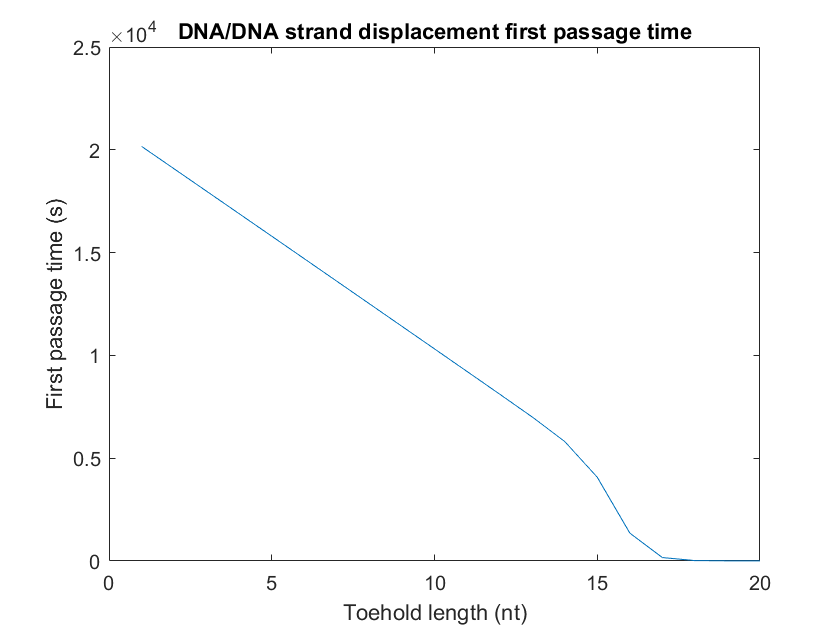

plot(1:20, first_pass_time)
ylabel('First passage time (s)')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement first passage time')

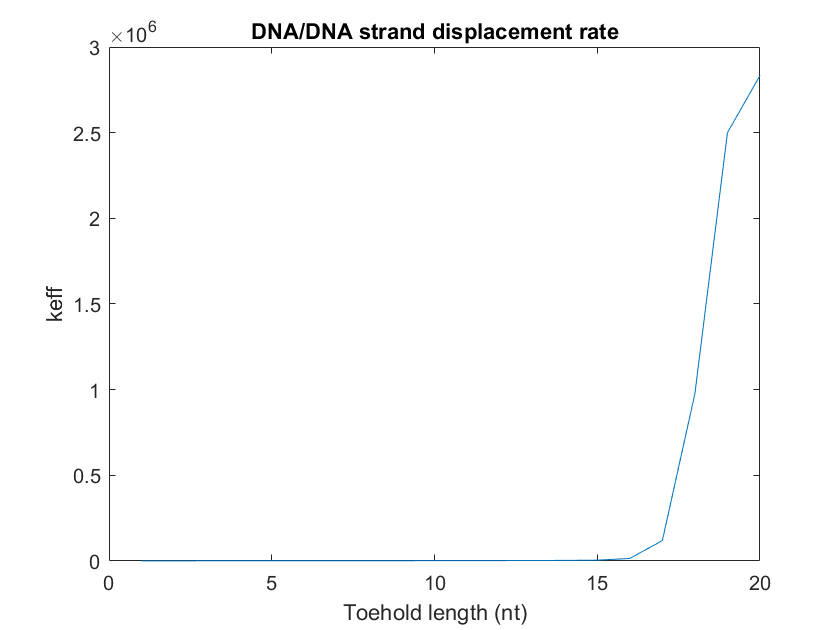


plot(1:20, k_eff)
xlabel('Toehold length (nt)')
ylabel('keff')
title('DNA/DNA strand displacement rate')

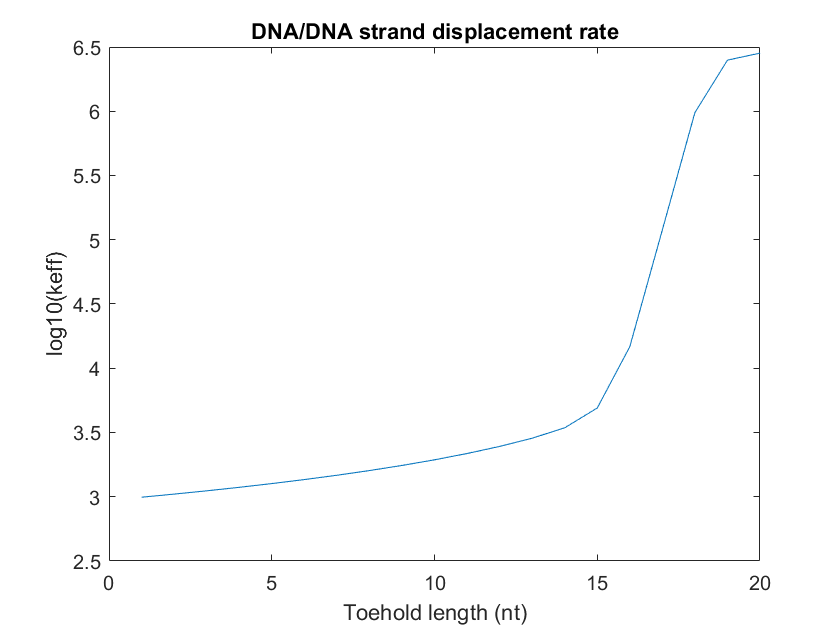


plot(1:20, log10(k_eff))
xlabel('Toehold length (nt)')
ylabel('log10(keff)')
title('DNA/DNA strand displacement rate') 

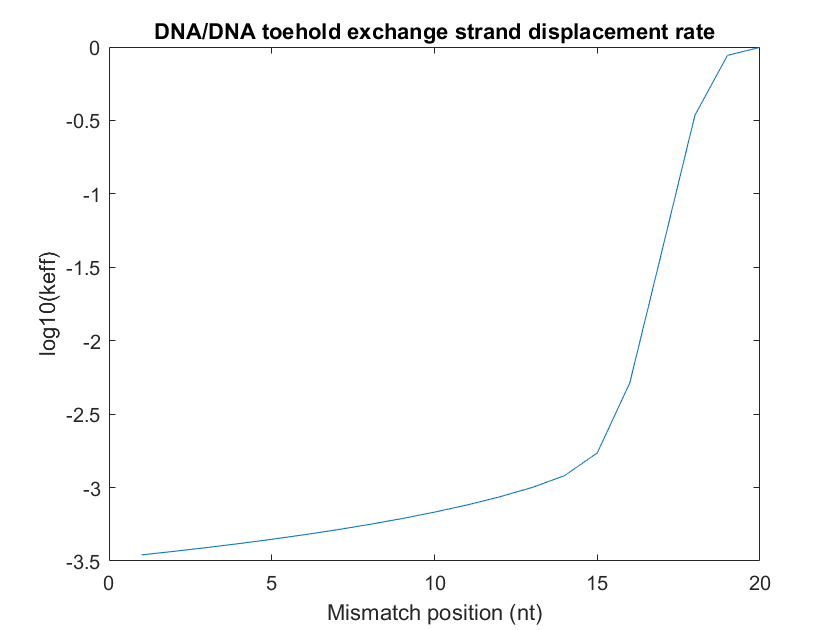


plot(1:20, log10(k_eff./k_eff_perf))
xlabel('Mismatch position (nt)')
ylabel('log10(keff)')
title('DNA/DNA toehold exchange strand displacement rate')  